System Parameters 

clear;
clc;

%QBall params
Mpayload = 0.3; %Kg

Mpayload = 0.3000

M = 1.4 + Mpayload;% Kg

M = 1.7000

Ixx = 0.03;

Ixx = 0.0300

Iyy = 0.03;

Iyy = 0.0300

Izz = 0.04;

Izz = 0.0400


L = .2;

L = 0.2000

Kyaw = 4;

Kyaw = 4


%QBall Actuator params
Kmotor = 120;

Kmotor = 120

wmotor = 15;

wmotor = 15


g=9.81;

g = 9.8100


%Input Transformation (U = InputTransformation*T)
InputTransformation = [1 1 1 1;
                       0 0 L -L;
                       L -L 0 0;
                       Kyaw Kyaw -Kyaw -Kyaw];

InputTransformation =     1.0000    1.0000    1.0000    1.0000
         0         0    0.2000   -0.2000
    0.2000   -0.2000         0         0
    4.0000    4.0000   -4.0000   -4.0000


                   
InvT = inv(InputTransformation);

InvT =     0.2500         0    2.5000    0.0625
    0.2500         0   -2.5000    0.0625
    0.2500    2.5000         0   -0.0625
    0.2500   -2.5000         0   -0.0625



%Initial Condition
x_init = 0;
y_init = 0;
z_init = 0;

xdot_init = 0;
ydot_init =0;
zdot_init = 0;

phi_init = 0;
theta_init =0;
psi_init =0;

phidot_init = 0;
thetadot_init = 0;
psidot_init =0;

%Linearized SISO Models

prp1 = -5+5j;
prp2 = -5-5j;
%prp1 = -4+4j;
%prp2 = -4-4j;
%pxy = -3.5;    %discrete
pxy = -2.5;     %continuous
py1 = -5+2j;
py2 = -5-2j;

%Pitch Control
Ap = [0 1 ;0 0];
Bp = [0;1/Iyy];
Cp=[1 0];
Dp=[0];
Pp= [prp1;prp2];
PitchSystem = ss(Ap,Bp,Cp,Dp);

PitchSystem =
 
  A = 
       x1  x2
   x1   0   1
   x2   0   0
 
  B = 
          u1
   x1      0
   x2  33.33
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Kp = place(Ap,Bp,Pp)

Kp =     1.5000    0.3000



%Roll Control
Ar = [0 1 ;0 0];
Br = [0;1/Ixx];
Cr=[1 0];
Dr=[0];
Pr= [prp1;prp2];
RollSystem = ss(Ar,Br,Cr,Dr);

RollSystem =
 
  A = 
       x1  x2
   x1   0   1
   x2   0   0
 
  B = 
          u1
   x1      0
   x2  33.33
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Kr = place(Ar,Br,Pr)

Kr =     1.5000    0.3000



%xdot Control 
Ax = [0];
Bx = [g];
Cx = [1];
Dx = [0];
Px= [pxy];
XDotSystem = ss(Ax,Bx,Cx,Dx);

XDotSystem =
 
  A = 
       x1
   x1   0
 
  B = 
         u1
   x1  9.81
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Kx = place(Ax,Bx,Px)

Kx = 0.2039


%yDot Control 
Ay = [0];
By = [-g];
Cy = [1];
Dy = [0];
Py= [pxy];
YDotSystem = ss(Ay,By,Cy,Dy);

YDotSystem =
 
  A = 
       x1
   x1   0
 
  B = 
          u1
   x1  -9.81
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Ky = place(Ay,By,Py)

Ky = -0.2039


%Yaw Control
Ayaw = [0 1;0 0];
Byaw = [0; 1/Izz];
Cyaw = [1 0];
Dyaw = [0];
Pyaw = [py1;py2];
YawSystem = ss(Ayaw,Byaw,Cyaw,Dyaw);

YawSystem =
 
  A = 
       x1  x2
   x1   0   1
   x2   0   0
 
  B = 
       u1
   x1   0
   x2  25
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Kyawc = place(Ayaw,Byaw,Pyaw)

Kyawc =     2.0000    0.4000




%Linear Control for Actuators
b = [0 Kmotor*wmotor];
a = [1 wmotor];
TFt = tf(b,a);

TFt =
 
   1800
  ------
  s + 15
 
Continuous-time transfer function.



[At, Bt, Ct, Dt] = tf2ss(b,a);

At = -15

Bt = 1

Ct = 1800

Dt = 0

Pt=[-15.5];

Pt = -15.5000

ActuatorSystem = ss(At,Bt,Ct,Dt);

ActuatorSystem =
 
  A = 
        x1
   x1  -15
 
  B = 
       u1
   x1   1
 
  C = 
         x1
   y1  1800
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Kt = place(At,Bt,Pt)

Kt = 0.5000


%Discretization of System

% Swiches Value
t_takeoff =20 ;
t_landing =20;
t_path = 30;
t_payloaddrop = 30; % Time value at which payload is dropped

%height control
Zref_TakeOff = 2;
zref_Landing = 0;
Takeoffspeed = Zref_TakeOff/t_takeoff;
Landingspeed = (zref_Landing-Zref_TakeOff)/t_landing;

%circle - path
t_circle = 30;
TimePeriodCircle = t_circle;
CircleRadius =2;

%square - path
t_square = 30;
t_squareLimit = t_square/4;
Squareref_Max = 4;
Squareref_Min = 0;
Squaremaxspeed = Squareref_Max/t_squareLimit;
Squareminspeed = (Squareref_Min-Squareref_Max)/t_squareLimit;

%Distritization of the continous plant

% Assume sample time is the minimum time between two mesurements from the
% IMU and atitude sensor
%Ts = 100e-3 % Sample Time 

Ts = 0.1000

Ts = 20e-3

PitchSystem_d =c2d(PitchSystem,Ts,'zoh');

PitchSystem_d =
 
  A = 
        x1   x2
   x1    1  0.1
   x2    0    1
 
  B = 
           u1
   x1  0.1667
   x2   3.333
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



RollSystem_d =c2d(RollSystem,Ts,'zoh');

RollSystem_d =
 
  A = 
        x1   x2
   x1    1  0.1
   x2    0    1
 
  B = 
           u1
   x1  0.1667
   x2   3.333
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



XSystem_d =c2d(XDotSystem,Ts,'zoh');

XSystem_d =
 
  A = 
       x1
   x1   1
 
  B = 
          u1
   x1  0.981
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



YSystem_d =c2d(YDotSystem,Ts,'zoh');

YSystem_d =
 
  A = 
       x1
   x1   1
 
  B = 
           u1
   x1  -0.981
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



YawSystem_d =c2d(YawSystem,Ts,'zoh');

YawSystem_d =
 
  A = 
        x1   x2
   x1    1  0.1
   x2    0    1
 
  B = 
          u1
   x1  0.125
   x2    2.5
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.




% Mapping of poles form s domain to z domain

#### $z = e^{sTs}$;

Pp_d = exp(Pp*Ts);

Pp_d =    0.5323 + 0.2908i
   0.5323 - 0.2908i


Pr_d = exp(Pr*Ts);

Pr_d =    0.5323 + 0.2908i
   0.5323 - 0.2908i


Px_d = exp(Px*Ts);

Px_d = 0.8187

Py_d = exp(Py*Ts);

Py_d = 0.8187

Pyaw_d = exp(Pyaw*Ts);

Pyaw_d =    0.5323 + 0.2908i
   0.5323 - 0.2908i



% Pole Placement for Closed Loop Discretized plant
Kp_d = place(PitchSystem_d.A,PitchSystem_d.B,Pp_d)

Kp_d =     0.9100    0.2351


Kr_d = place(RollSystem_d.A,RollSystem_d.B,Pr_d)

Kr_d =     0.9100    0.2351


Kx_d = place(XSystem_d.A,XSystem_d.B,Px_d)

Kx_d = 0.1848

Ky_d = place(YSystem_d.A,YSystem_d.B,Py_d)

Ky_d = -0.1848

Kyaw_d = place(YawSystem_d.A,YawSystem_d.B,Pyaw_d)

Kyaw_d =     1.2133    0.3135


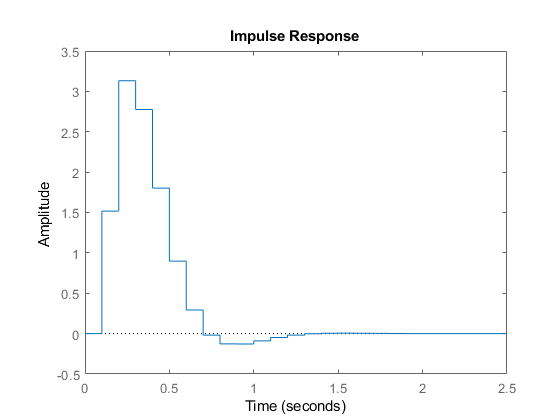


% Closed for discrited pitch system
sys_Pitch_d = ss(PitchSystem_d.A-PitchSystem_d.B*Kp_d,PitchSystem_d.B*Kp_d(1),PitchSystem_d.C,PitchSystem_d.D,Ts);
figure(1)
impulse(sys_Pitch_d) 

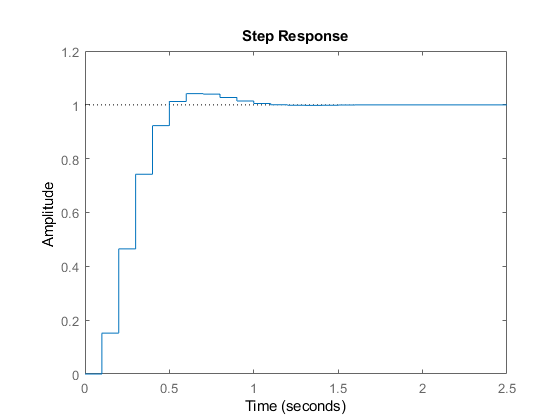

figure(2)
step(sys_Pitch_d)